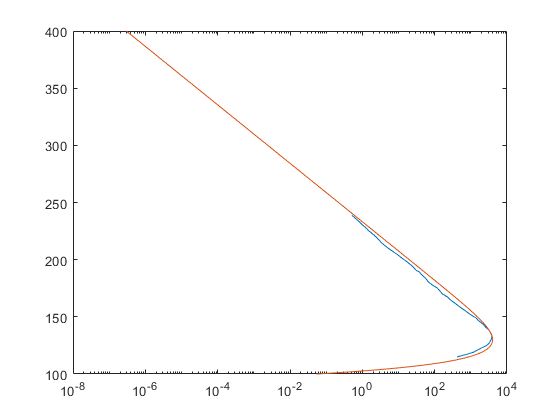

clearvars;

raw = [417.07726649325366, 114.87596017729922,537.5721363826498, 115.92583138010258,753.8801325394643, 117.14789631245506,1150.8075017130102, 118.89768165046067,1501.46174292601, 120.767463533106,2018.3103682975852, 122.92994805673669,2779.1184674187916, 125.01772667224543,3339.1667963562295, 127.66772124011051,3757.7001902667143, 131.1813011588987,3807.766987146073, 133.75182752779006,3169.495595741495, 138.56396927432644,2684.334592082454, 140.3527418718526,2183.5641285287106, 143.56640597804648,1598.8475636449195, 146.787032094869,1412.9225426201479, 148.92854656424777,962.666426023602, 152.0326431028762,745.7299105362672, 154.74845720016336,514.465649988609, 158.27282730382387,359.70112198438704, 162.08211492342397,273.86552804836003, 164.7591100436041,222.66127095143048, 167.53321269854865,167.58438243886678, 169.75868472631765,139.4365145839819, 172.5834593596278,115.1349738906686, 175.58096095975606,94.86428125361378, 177.0184029147618,79.51256558662685, 178.6082005441013,65.38978406845195, 180.86491903111198,57.151892567872196, 183.55956371869675,44.29322362927219, 186.6523166021882,37.40291262121403, 189.3963956441596,30.326979120351307, 190.78276206168343,25.72227964477728, 193.47141934185873,20.897758760508314, 195.96296210345548,17.102791304619043, 198.17007310323606,11.757208714007465, 201.9321913582278,9.10774556027921, 204.64973983643307,6.933431951109265, 207.21753833400848,5.369350858963181, 209.6853359600048,4.23077788014281, 212.2196332825613,3.391434904538237, 214.70769554200035,2.815205556105404, 217.54173917130473,2.3766067469339958, 220.05898431426525,1.938019037136333, 222.44947383541057,1.4268062980314955, 225.85870150523087,1.2170266863784645, 228.15112204404633,0.9891231390251883, 230.65373279803208,0.8557152202822865, 232.61887633148456,0.6812890353048406, 235.47840616370007,0.5202927636765419, 238.69624747627117];

i = 1;
while i <= length(raw)-1
    rawx(ceil(i/2)) = raw(i);
    rawy(ceil(i/2)) = raw(i+1);
    i = i+2;
end

Zm = 130;
H = 11.1;
Qm = 4e3;

fun = @(z) Qm*exp(1-((z-Zm)/H)-exp(-((z-Zm)/H)));


extrap_y = 100:400;
extrap_x = fun(extrap_y);

newx = fun(rawy);

semilogx(rawx,rawy);
hold on;
semilogx(extrap_x,extrap_y);
ylim([100,400]);

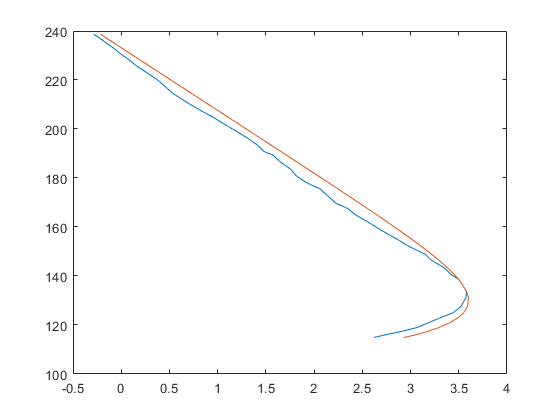





lograwx = log10(rawx);
lognewx = log10(newx);
figure;
plot (lograwx,rawy,lognewx,rawy)



X2(rawx,newx)

ans = 3.0224e+03

X2(lograwx,lognewx)

ans = 1.2874

function out = X2(O,E)
    out = 0;
    for i=1:length(O)
        out = out + (O(i)-E(i))^2/E(i); 
    end
end